% Đường dẫn đến thư mục chứa các thư mục chứa ảnh và nhã hiện tại
parentDir = 'C:\Users\Admin\OneDrive\HocTap\Research\db_data\xview\data\train';

% Đường dẫn đến thư mục lưu trữ ảnh mới
outputDir = 'C:\Users\Admin\OneDrive\HocTap\Research\Remotesesing\xview\data\train\images';

% Tạo thư mục mới để lưu ảnh và nhãn đã gom
mkdir(outputDir);



% Đường dẫn đến thư mục lưu trữ nhãn mới
outputDir = 'C:\Users\Admin\OneDrive\HocTap\Research\Remotesesing\xview\data\train\labels';

% Tạo thư mục mới để lưu ảnh và nhãn đã gom
mkdir(outputDir);


% Đường dẫn đến thư mục lưu trữ ảnh và nhãn mới
outputDir = 'C:\Users\Admin\OneDrive\HocTap\Research\Remotesesing\xview\data\train';

% Đường dẫn đến thư mục ảnh và labels trong thư mục sq hiện tại
    imagesDir = fullfile(parentDir, 'images');
    labelsDir = fullfile(parentDir, 'labels');
    
    % Đọc danh sách tất cả các tệp ảnh trong thư mục images
    imageFiles = dir(fullfile(imagesDir, '*.tif')); % hoặc định dạng tệp ảnh khác

    %Đọc các file label .json
     labelFile = dir(fullfile(labelsDir, '*.json')); % hoặc định dạng tệp ảnh khác



labelNameFile = 'guatemala-volcano_00000004_post_disaster.json'

labelNameFile = 'guatemala-volcano_00000004_pre_disaster.json'

labelNameFile = 'guatemala-volcano_00000012_post_disaster.json'

labelNameFile = 'guatemala-volcano_00000012_pre_disaster.json'

labelNameFile = 'guatemala-volcano_00000014_post_disaster.json'

labelNameFile = 'guatemala-volcano_00000014_pre_disaster.json'

labelNameFile = 'guatemala-volcano_00000020_post_disaster.json'

labelNameFile = 'guatemala-volcano_00000020_pre_disaster.json'

labelNameFile = 'guatemala-volcano_00000022_post_disaster.json'

labelNameFile = 'guatemala-volcano_00000022_pre_disaster.json'

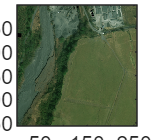

for indexImg = 1:10   %length(imageFiles)

    %Đọc ảnh 
    imgFileName = imageFiles(indexImg).name;
    originalImage = imread(fullfile(imagesDir, imgFileName));
    

    %Quá trình biến đổi từ uint16 về int8
    vector_img = originalImage(:);
    unit8_vector = typecast(vector_img,'uint8');
    unit8_vector = unit8_vector(1:2:end);
    unit8_matrix= reshape(unit8_vector,1024,1024,3); %Kich thuoc ban dau
    %Resize ảnh
    resizedImage = imresize(unit8_matrix, 0.25 );
    
   % test label
   %Đọc file json
    labelNameFile = labelFile(indexImg).name
    fname = fullfile(labelsDir, labelNameFile); 
    fid = fopen(fname); 
    raw = fread(fid,inf); 
    str = char(raw'); 
    fclose(fid); 
    val = jsondecode(str);

    h = image(resizedImage);
    colormap(gray);
    hold on;
    for i = 1:numel(val.features.xy)
        polygonString = val.features.xy(i).wkt;
        polygonString_x_y = erase(polygonString, {'POLYGON ((', '))'});
        % Chuyển chuỗi thành mảng tọa độ
        coordinates = str2num(polygonString_x_y); % Chuyển chuỗi thành mảng số
        % Chia mảng tọa độ thành các tọa độ x và y
        x = coordinates(1:2:end)/4;
        y = coordinates(2:2:end)/4;
     if isfield(val.features.xy(i).properties, 'subtype')
        damageLevel = val.features.xy(i).properties.subtype;
        switch damageLevel
        case 'no-damage'
            color = [0, 0, 1]; % Blue
        case 'major-damage'
            color = [1, 1, 0]; % Yellow
        case 'minor-damage'
            color = [1, 0.65, 0]; % Orange
        case 'destroyed'
            color = [1, 0, 0]; % Red
            otherwise
            color = [0, 0, 0]; % Black (default)
        end
    else
        color = [0, 0, 0];
    end
        fill(x, y, color,'EdgeColor', 'none','FaceAlpha',1);
    end
    hold off;
    saveas(h,strcat('C:\Users\Admin\OneDrive\HocTap\Research\Remotesesing\xview\data\train\testpng',string(indexImg),'.png'));
   %Lưu ảnh vào thư mục mới
   %outputImgPath = fullfile(outputDir, 'images',imgFileName);
   %imwrite(unit8_matrix_resize, outputImgPath);
end